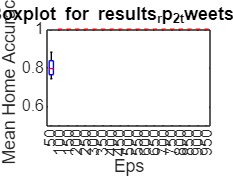

directory = 'C:\Users\samue\Desktop\ppia-project';
files = dir('C:\Users\samue\Desktop\ppia-project\results*.csv');

% Iterate through the files and generate boxplots with labels
for i = 1:length(files)
    filepath = sprintf('C:\\Users\\samue\\Desktop\\ppia-project\\%s', files(i).name); % Construct file path
    results = readtable(filepath);
    
    % Create boxplot
    boxplot(results.mean_home_accuracy, results.eps);
    ylim([0.5, 1]); % Set y-axis limits
    
    % Add labels and title
    xlabel('Eps (m)'); % X-axis label
    ylabel('Mean Home Accuracy'); % Y-axis label
    title(sprintf('Boxplot for %s', files(i).name)); % Title of the plot
    
    % Save the plot as a PNG file
    figure_name = sprintf("boxplot_%s.png", files(i).name);
    saveas(gcf, figure_name);
end